# Example: COVID-2019 data (22-Jan-2020-15-Mar-2020)

I am taking some data from Hubei province from John Hopkins university [1]

[1] https://github.com/CSSEGISandData/COVID-19

## Initialisation

The parameters are here taken as constant except the death rate and the cure rate.

clearvars;close all;clc;
load('HubeiData.mat','time','Deaths','Infected','Recovered')
dt = 0.1; % time step
time1 = datetime(time(1)):dt:datetime(2020,04,01,0,0,0);
N = numel(time1);
t = [0:N-1].*dt;
Npop= 14e6; % population

## Fitting of the generalized SEIR model to the real data

guess = [0.08,1,1/5,1/40,0.05,0.02]; % my guess for the fit
[alpha1,beta1,gamma1,delta1,Lambda1,Kappa1] = ...
    fit_SEIQRDP(Infected-Recovered,Recovered,Deaths,Npop,time,guess);


                                         Norm of      First-order 
 Iteration  Func-count     f(x)          step          optimality
     0          7     8.73049e+10                      1.38e+13
     1         14     2.58837e+10       0.282986       1.04e+12      
     2         21     7.84595e+09       0.315535       1.42e+11      
     3         28      8.6485e+08       0.108103       8.55e+11      
     4         35     4.04458e+08      0.0749343        8.6e+10      
     5         42     3.92759e+08        1.06103       2.73e+08      
     6         49     3.92759e+08       0.927448       2.73e+08      
     7         56     3.92759e+08       0.231862       2.73e+08      
     8         63     3.92253e+08      0.0579655        8.6e+08      
     9         70      3.9193e+08      0.0579655       1.06e+08      
    10         77      3.9193e+08       0.115931       1.06e+08      
    11         84      3.9165e+08      0.0289827       1.28e+08      
    12         91     3.91303e+0

## Simulate the epidemy outbreak based on the fitted parameters

E0 = 0; % Initial number of exposed cases (we do not know it, so it is set at zero)
I0 = Infected(1);
R0 = Recovered(1);
D0 = Deaths(1);
N = numel(time1);
t = [0:N-1].*dt;
[S,E,I,Q,R,D,P] = SEIQRDP(alpha1,beta1,gamma1,delta1,Lambda1,Kappa1,Npop,E0,I0,R0,D0,t);

## Comparison of the fited and real data

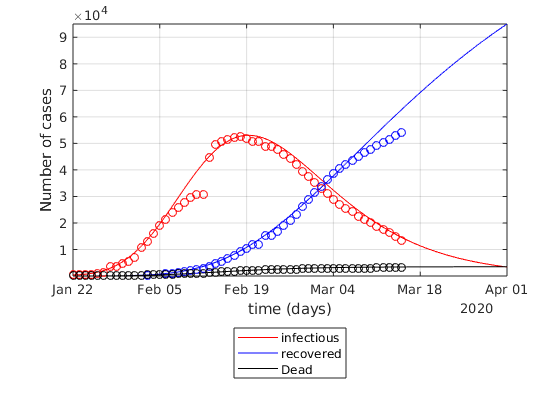

figure
semilogy(time1,I,'r',time1,R,'b',time1,D,'k');
hold on
semilogy(time,Infected-Recovered,'ro',time,Recovered,'bo',time,Deaths,'ko');
% ylim([0,1.1*Npop])
ylabel('Number of cases')
xlabel('time (days)')
% leg = {'susceptible','exposed','infectious','quarantined','recovered','Dead','insusceptible'};
leg = {'infectious','recovered','Dead'};
legend(leg{:},'location','southoutside')
set(gcf,'color','w')
grid on
axis tight
% ylim([1,8e4])
set(gca,'yscale','lin')